close all;
addpath('./Geometry-Toolbox/');
clear;

%% System Parameters
quad_params.params.mass = 0.5;  % mass in kg
quad_params.params.J = diag([0.557, 0.557, 1.05] * 10e-2);  % Moment of inertia
quad_params.params.e1 = [1; 0; 0];  % Inertial frame axis e1
quad_params.params.e2 = [0; 1; 0];  % Inertial frame axis e2
quad_params.params.e3 = [0; 0; 1];  % Inertial frame axis e3
quad_params.params.g = 9.81;  % gravitational constant
quad_params.params.kp = [5; 5; 9];  % Position control gains
quad_params.params.kd = [7; 7; 10]; % Velocity control gains
quad_params.params.kphi = 10;  % Euler angle gains
quad_params.params.komega = 10;  % Angular velocity gains

% Initial conditions
x0 = [0; 0; 0];       % Position
v0 = [0; 0; 0];       % Velocity
angles0 = [0; 0; 0];  % Roll, Pitch, Yaw (Euler angles)
omega0 = [0; 0; 0];   % Angular velocity

% Initial state vector
initial_state = [x0; v0; angles0; omega0];

%% Simulation
odeopts = odeset('RelTol', 1e-8, 'AbsTol', 1e-9);
[t, state] = ode15s(@quad_dynamics, [0 20], initial_state, odeopts, quad_params);

%% Compute Various Quantities
disp('Evaluating...');

Evaluating...


Plotting graphs...


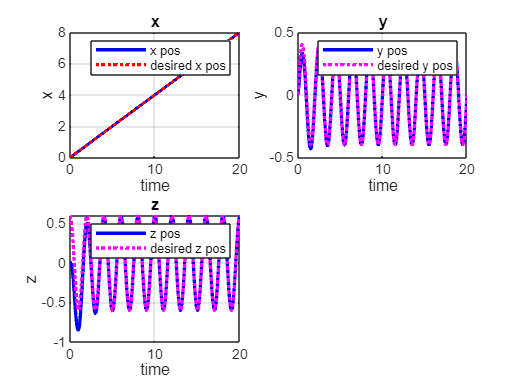

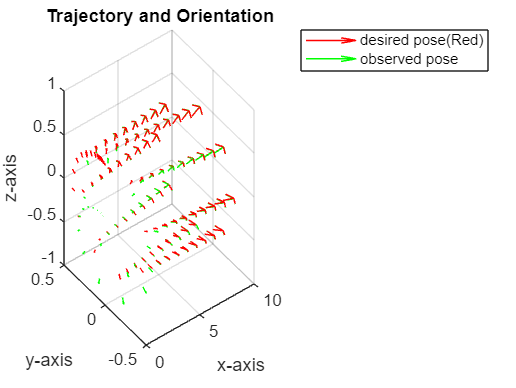

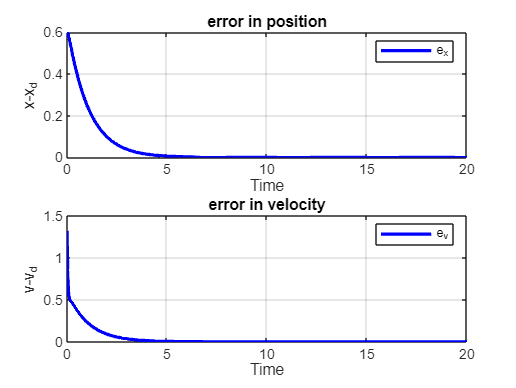

index = round(linspace(1, length(t), round(1 * length(t))));

for i = index
    [~, xd_, f_, M_,angles_des] = quad_dynamics(t(i), state(i,:)', quad_params);
    xd(i, :) = xd_';
    angles(i,:)=angles_des';

    pos_err_fx(i) = norm(state(i, 1:3) - xd(i, 1:3));
    vel_err_fx(i) = norm(state(i, 4:6) - xd(i, 4:6));

    roll=state(i,7);
    pitch=state(i,8);
    yaw=state(i,9);
    
    % Rotation matrix from roll, pitch, yaw
    R_roll = [1, 0, 0; 0, cos(roll), -sin(roll); 0, sin(roll), cos(roll)];
    R_pitch = [cos(pitch), 0, sin(pitch); 0, 1, 0; -sin(pitch), 0, cos(pitch)];
    R_yaw = [cos(yaw), -sin(yaw), 0; sin(yaw), cos(yaw), 0; 0, 0, 1];
    R = R_yaw * R_pitch * R_roll;

    hi(i,1:3) = (R * state(i,1:3)')';

    roll=angles(i,1);
    pitch=angles(i,2);
    yaw=angles(i,3);
    
    % Rotation matrix from roll, pitch, yaw
    R_roll = [1, 0, 0; 0, cos(roll), -sin(roll); 0, sin(roll), cos(roll)];
    R_pitch = [cos(pitch), 0, sin(pitch); 0, 1, 0; -sin(pitch), 0, cos(pitch)];
    R_yaw = [cos(yaw), -sin(yaw), 0; sin(yaw), cos(yaw), 0; 0, 0, 1];
    R = R_yaw * R_pitch * R_roll;

    hi_d(i,1:3) = (R * xd(i,1:3)')';

end

%% Plotting Results
plot_results(t, state,xd, pos_err_fx, vel_err_fx,hi,hi_d);


%% Quadrotor Dynamics
function [ds,sd,u1,tau,angles_des] = quad_dynamics(t, s, quad_params)
    % Extract parameters
    m = quad_params.params.mass;
    J = quad_params.params.J;
    g = quad_params.params.g;
    kp = quad_params.params.kp;
    kd = quad_params.params.kd;
    kphi = quad_params.params.kphi;
    komega = quad_params.params.komega;
    e3 = quad_params.params.e3;

    % Current states
    x = s(1:3);          % Position
    v = s(4:6);          % Velocity
    angles = s(7:9);     % Roll, Pitch, Yaw
    omega = s(10:12);    % Angular velocity

    % Desired trajectory
    traj = desired_trajectory(t);
    pos_des = traj.pos;     % Desired position
    vel_des = traj.vel;     % Desired velocity
    acc_des = traj.acc;     % Desired acceleration
    yaw_des = traj.yaw;     % Desired yaw

    % Position Control (Force)
    pos_err = x - pos_des;
    vel_err = v - vel_des;
    u1 = -diag(kp) * pos_err - diag(kd) * vel_err + m * acc_des + m * g * e3;

    % Desired roll, pitch, and yaw (Euler angles)
    phi_des = (1/g) * (u1(1) * sin(yaw_des) - u1(2) * cos(yaw_des));
    theta_des = (1/g) * (u1(1) * cos(yaw_des) + u1(2) * sin(yaw_des));
    psi_des = yaw_des;

    angles_des = [phi_des; theta_des; psi_des];

    % Attitude Control (Torque)
    angle_err = angles - angles_des;
    omega_err = omega;

    tau = -kphi * angle_err - komega * omega;

    % Equations of Motion
    x_dot = v;
    v_dot = -g * e3 + (u1 / m);
    angles_dot = omega;
    omega_dot = J \ (tau - cross(omega, J * omega));

    %% Desired state
    sd = [pos_des; vel_des; acc_des; yaw_des];
    
    % State Derivative
    ds = [x_dot; v_dot; angles_dot; omega_dot];
end

%% Desired Trajectory Function
function traj = desired_trajectory(t)
    traj.pos = [0.4*t; 0.4*sin(pi*t); 0.6*cos(pi*t)];
    traj.vel = [0.4; 0.4*pi*cos(pi*t); -0.6*pi*sin(pi*t)];
    traj.acc = [0; -0.4*pi*pi*sin(pi*t); -0.6*pi*pi*cos(pi*t)];
    traj.yaw = 0;  % Desired yaw angle
end

% end
function plot_results(t, state, xd, pos_err_fx, vel_err_fx,hi,hi_d)
    disp('Plotting graphs...');
    index = round(linspace(1, length(t), round(1 * length(t))));

    figure;
    subplot(2, 2, 1);
    plot(t(index), state(index, 1), '-b', 'LineWidth', 2); hold on;
    plot(t(index), xd(index, 1), ':r', 'LineWidth', 2); hold off;
    grid on; title('x'); legend('x pos', 'desired x pos'); xlabel('time'); ylabel('x');

    subplot(2, 2, 2);
    plot(t(index), state(index, 2), '-b', 'LineWidth', 2); hold on;
    plot(t(index), xd(index, 2), ':m', 'LineWidth', 2); hold off;
    grid on; title('y'); legend('y pos', 'desired y pos'); xlabel('time'); ylabel('y');

    subplot(2, 2, 3);
    plot(t(index), state(index, 3), '-b', 'LineWidth', 2); hold on;
    plot(t(index), xd(index, 3), ':m', 'LineWidth', 2); hold off;
    grid on; title('z'); legend('z pos', 'desired z pos'); xlabel('time'); ylabel('z');
    % 
    figure
    
    
    quiver3(xd(1:15:end, 1), xd(1:15:end, 2), xd(1:15:end, 3), 0.5*hi_d(1:15:end,1),  0.5*hi_d(1:15:end,2),0.5*hi_d(1:15:end,3), 'r'); hold on;
    quiver3(state(1:15:end, 1), state(1:15:end, 2), state(1:15:end, 3), 0.5*hi(1:15:end,1),  0.5*hi(1:15:end,2),0.5*hi(1:15:end,3), 'g');
    
    hold off;
    grid on;
    title('Trajectory and Orientation');
    legend('desired pose(Red)','observed pose');
    xlabel('x-axis'); ylabel('y-axis'); zlabel('z-axis');

    % Plot position and velocity errors
    figure;
    subplot(2,1,1);
    plot(t(index),pos_err_fx(index),'-b','LineWidth',2);
    grid on; title('error in position');
    legend('{e}_x');
    xlabel('Time');ylabel('{x}-{x}_d');
    subplot(2,1,2);
    plot(t(index),vel_err_fx(index),'-b','LineWidth',2);
    grid on; title('error in velocity');legend('{e}_v');
    xlabel('Time');ylabel('{v}-{v}_d');

end

